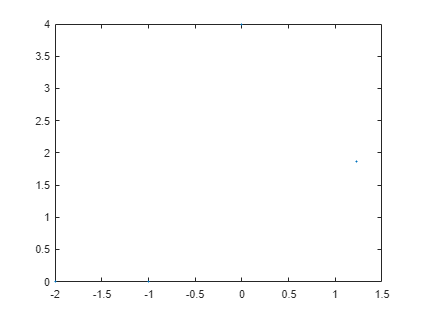

clear; close; clc;

%fplot(@(x) )


nPointsXi = 21;
nPointsEta = 41;

% nPointsXi = 41;
% nPointsEta = 81

% nPointsXi = 161;
% nPointsEta = 321

% nPointsXi = 321;
% nPointsEta = 641


% mesh corners
s2 = 1 / cos(pi/6);
s6 = (4 - s2) * sin(pi/6);

corners = ...
    [
    -2, 0
    -1, 0
    0, 4
    s6 * cos(pi/6), s2 + s6 * sin(pi/6)
    ];

plot(corners(:,1), corners(:,2), '.');


% mesh edges
syms t;
sympref("HeavisideAtOrigin",.5); % to make it well conditioned at overlap

x_ic = corners(4,1);

% make the arc - note this is naturally paramterized 
xInnerArc = cos(t-pi);
yInnerArc = -sin(t-pi);

% now arc length parameterization
% semi circ is arc len paramterized already
% line is needs be scaled by 1/mag to be arc length parameterized 
magInner = 5585394183300118827385933267443^(1/2)/1125899906842624

magInner = 2.0991

xInnerLine = -1/2 + ((x_ic + 1/2) / (2 - pi/3)) * (t - pi/3)/magInner;
yInnerLine = sqrt(3)/2 + tan(pi/6) * (xInnerLine + 1/2);

t_s = pi/3;
xInner = xInnerArc * heaviside(-t+t_s) + xInnerLine * heaviside(t-t_s);
yInner = yInnerArc * heaviside(-t+t_s) + yInnerLine * heaviside(t-t_s);

fInner = [xInner, yInner]

$$fInner = \begin{array}{l} \left(\begin{array}{cc} -\sigma_{2}\,\left(\frac{1364477211645559\,\pi }{4726687712680041}-\frac{1364477211645559\,t}{1575562570893347}+\frac{1}{2}\right)-\sigma_{1}\,\cos\left(t\right) & \sigma_{2}\,\left(\frac{\sqrt{3}}{2}+\frac{\sqrt{3}\,\left(\frac{1364477211645559\,t}{1575562570893347}-\frac{1364477211645559\,\pi }{4726687712680041}\right)}{3}\right)+\sigma_{1}\,\sin\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{heaviside}\left(\frac{\pi }{3}-t\right)\\ \sigma_{2}=\mathrm{heaviside}\left(t-\frac{\pi }{3}\right) \end{array}$$

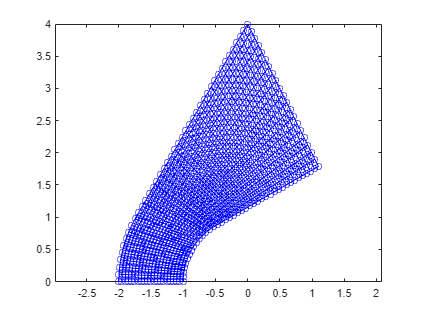


% find the total arc length
r_inner = 1;
theta_inner = pi/3;
y_ic = corners(4,2);
AlenInner =  r_inner * theta_inner + sqrt((x_ic + 1/2)^2 + (y_ic - sqrt(3/2))^2);


% outer

% arc length parameterised circle
xOuterArc = 2 * cos(t/2-pi);
yOuterArc = -2 * sin(t/2-pi);

% compute line parameterised by arc length
x1 = -2 * sqrt(3)/2;
y1 = 2 * 1/2;

magOut = 4093431634936677/1125899906842624; % adjustment factor for acr length parameterization

xOuterLine = x1 - x1/(2*(1-pi/6)) * (t - 2*pi/6)/(magOut);
yOuterLine = y1 + tan(pi/3) * (xOuterLine-x1);

% assemble the final function
t_s = 2*pi/6;
xOuter = xOuterArc * heaviside(-t+t_s) + xOuterLine * heaviside(t-t_s);
yOuter = yOuterArc * heaviside(-t+t_s) + yOuterLine * heaviside(t-t_s);

fOuter = [xOuter, yOuter];

% find the total arc length
r_outer = 2;
theta_outer = pi/6;
x_oc = corners(3,1);
y_oc = corners(3,2);
AlenOuter =  r_outer * theta_outer + sqrt((x_oc - x1)^2 + (y_oc - y1)^2);
%AlenOuter = 4*pi/6 + sqrt((x_oc - x1)^2 + (y_oc - y1)^2)

% plot inner
timeInner = linspace(0,AlenInner, nPointsEta)'; % unsure of what total arc length to use yet
% it will be r*theta + (Deltax^2+Deltay^2)^(1/2)

innerPoints = double(subs(fInner,t,timeInner));
plot(innerPoints(:,1), innerPoints(:,2), 'k- o');
hold on;


% plot outer
timeOuter = linspace(0,AlenOuter, nPointsEta)'; % unsure of what total arc length to use yet
% it will be r*theta + (Deltax^2+Deltay^2)^(1/2)

outerPoints = double(subs(fOuter,t,timeOuter));
plot(outerPoints(:,1), outerPoints(:,2), 'k- o');
hold on;

% mesh the area


for edgeIndex = 1:nPointsEta
    xcoords = linspace(innerPoints(edgeIndex,1), outerPoints(edgeIndex,1), nPointsXi)';
    ycoords = linspace(innerPoints(edgeIndex,2), outerPoints(edgeIndex,2), nPointsXi)';
    Mesh(edgeIndex, :, :) = [xcoords, ycoords];
    plot(Mesh(edgeIndex, :, 1), Mesh(edgeIndex, :, 2), 'b- o');
end


%plot the grid
for spaceIndex = 1:nPointsXi
    line = zeros([nPointsEta, 2]);
    for edgeIndex = 1:nPointsEta
        %line = [Surf(spaceIndex, 1, edgeIndex), Surf(spaceIndex, 2, edgeIndex)];
        line(edgeIndex,:) = [Mesh(edgeIndex, spaceIndex, 1), Mesh(edgeIndex, spaceIndex, 2)];
    end
    plot(line(:,1),line(:,2),  'b- o');
end
axis equal;


Filename = sprintf("2D_Mesh_%g_by_%g", nPointsEta, nPointsXi);
save(Filename,"Mesh");

% for edgeIndex = 1:nPointsXi
%     plot(Surf(edgeIndex,:,1), Surf(edgeIndex,:,1), 'b- o');
% end